cAMPFreSimvsAnaSolu

无量纲化分析 考虑bPAC瞬间失活 

[https://jinlab.yuque.com/vwt6oc/bu7rel/guwgitem33kes6wf](https://jinlab.yuque.com/vwt6oc/bu7rel/guwgitem33kes6wf)

2.3.1 和2.3.2 理论解析解与数值积分比较

Shuai Yang 

2023/7/5

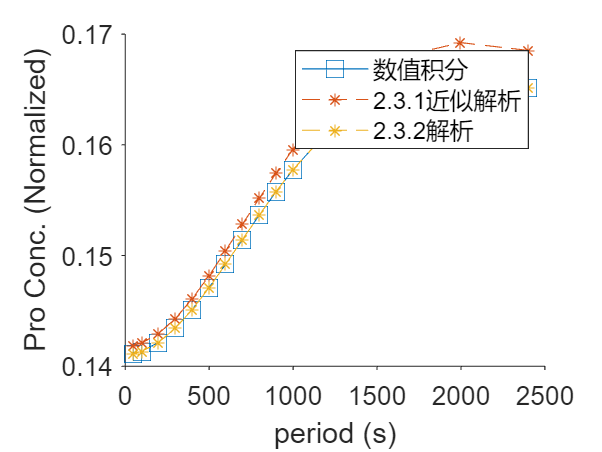

% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.0045;% 默认 0.0045 uM/s
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
% T = 1000;% 信号输入的周期 s
P = 0.1;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
%%
% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM
Vfr = 0.27;% uM TF因子数目 默认0.27
DNA = 0.05; % uM 启动子的DNA数目
lambda = Vfr/K2;


Tset = [50,100:100:1000,1200:400:2400];
% xTickNames = string(Tset);
y_output1 = NaN(size(Tset));
y_output2 = NaN(size(Tset));
y_output3 = NaN(size(Tset));
x_HL = NaN(2,numel(Tset));
s_HL = NaN(2,numel(Tset));

for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid); 

    x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));

    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

    a = k/gamma;
    phi = gamma*T;
    tao = gamma*t;

    % sH = x_High/a;
    % sL = x_Low/a;

    sH = (1-exp(-phi*P))/(1-exp(-phi));
    sL = (exp(phi*P)-1)/(exp(phi)-1);

    dtao = dt*gamma;
    s_tao = (1-(1-sL)*exp(-tao)).*(tao<=phi*P)+...
        (sH*exp(-tao+phi*P)).*(tao>phi*P);

    % 验证
    % figure,plot(x);hold on,plot(s_tao*a,'--');% 两条曲线重合

    theta = lambda*(a/K1)^2;
    alpha = k/(gamma*K1);



    % 针对 lambda远远大于1 的近似情况 瞬间失活的 积分
    y = (1/phi)*((theta/(1+theta)*log((1-sL)*sqrt(1+theta*(sH)^2)/((1-sH)*sqrt(1+theta*(sL)^2))))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))));


    sH1 = sinh(phi*P/2)/sinh(phi/2)*exp(phi*(1-P)/2);
    sL1 = sinh(phi*P/2)/sinh(phi/2)*exp(-phi*(1-P)/2);

    testP = 1/phi*log((1-sL)/(1-sH));

    y_test = (1/phi)*((theta/(1+theta)*log(sqrt(1+theta*(sH)^2)/sqrt(1+theta*(sL)^2)))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))))+theta*P/(1+theta);


    % 不针对 lambda大于1 进行近似
    y1 = (1/phi)*((lambda*alpha^2/(1+(lambda+1)*alpha^2))*log(sqrt(1+(lambda+1)*alpha^2*sH^2)/sqrt(1+(lambda+1)*alpha^2*sL^2))-...
        alpha*lambda/sqrt(lambda+1)/(1+(lambda+1)*alpha^2)*atan(alpha*sqrt(lambda+1)*(sH-sL)/(1+(lambda+1)*alpha^2*sL*sH)))+...
        lambda*alpha^2*P/(1+(lambda+1)*alpha^2);

    x1 = x/K1;
    u = lambda./((1+lambda)+1./x1.^2);
    u1 = cAMPOutPut1(t,T,k,gamma,P,lambda,K1);

    fun =@(t,T) cAMPOutPut1(t,T,k,gamma,P,lambda,K1);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;

    y_output1(iPeroid) = q1;% 数值积分
    y_output2(iPeroid) = y; % bPAC 瞬间失活 针对λ远大于1的近似
    y_output3(iPeroid) = y1;% bPAC 瞬间失活 一般情况未近似

    x_HL(1,iPeroid) = x_High;
    x_HL(2,iPeroid) = x_Low;
    s_HL(1,iPeroid) = sH1;
    s_HL(2,iPeroid) = sL1;

end

f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,y_output1,'Marker','square','MarkerSize',10,'DisplayName','数值积分')
hold on,plot(Tset,y_output2,'LineStyle','--','Marker','*','DisplayName','2.3.1近似解析')
hold on,plot(Tset,y_output3,'LineStyle','--','Marker','*','DisplayName','2.3.2解析')

set(ax1,'Tickdir','out','Box','off','FontSize',12);
legend(ax1,'show')
xlabel(ax1,'period (s)')
ylabel(ax1,'Pro Conc. (Normalized)')

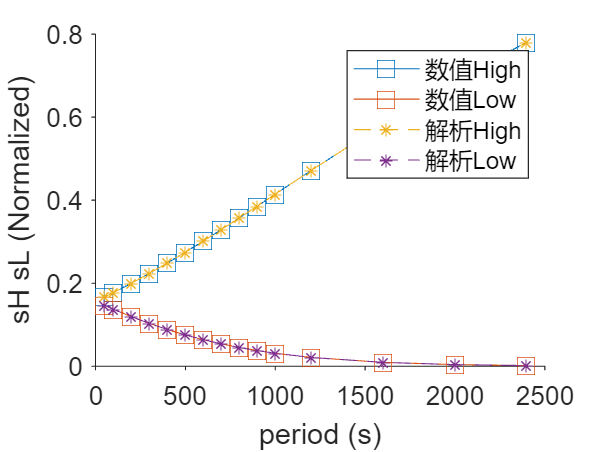


f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset,x_HL,'Marker','square','MarkerSize',10)
hold on,plot(Tset,s_HL*a,'LineStyle','--','Marker','*')
legend('数值High','数值Low','解析High','解析Low')
legend(ax1,'show')
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'period (s)')
ylabel(ax1,'sH sL (Normalized)')

function u = cAMPOutPut1(t,T,k,gamma,P,lambda,K1)
% bPAC 瞬间失活的情况 beta的事情
% 光照结束既是cAMP浓度最高时

x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
x_Low = x_High*exp(-gamma*(T-T*P));

x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
    (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

x1 = x/K1;
u = lambda./((1+lambda)+1./x1.^2);
end